## Insert Data

load ('subject_data.mat')

## Clean Up and Organize Data

Remove unnecessary data/information

% Remove unnecessary information
data_table = removevars(data_table,{'ID_test','VE','RR','VCO2'});
subject_info = removevars(subject_info,{'Humidity','Temperature','ID_test'});

% Remove subjects with missing Data 
subject_info = rmmissing(subject_info); 
data_table = rmmissing(data_table); 

% Remove multiple data collections for same subject 
% (keep the first data collection)
[~,row] = unique(subject_info.ID);
subject_info = subject_info(row,:);

% Removes data with speed less than 5.1 km/hr. This is to make sure that
% there is consistency in the measurements that are being compared between
% subjects. 
idx = any(data_table.Speed < 5.1,2);
[row,~] = find(idx);
data_table(row,:) = [];

% Create categorical for gender. For purposes of dataset analysis. 
subject_info.Sex = categorical(subject_info.Sex,[0,1],{'Male','Female'});

Organize Data into Structure for each Subject 

% Initialize structure to store information for each subject
subject = struct;

% Add relevant field to "subjects" structure
x = 1;
for idx = 1:numel(subject_info.ID)
    row = data_table.ID == subject_info.ID(x);
    
    % This conditional checks to make sure that there is caridiovascular
    % data associated with the subject
    if ~isempty(data_table(row,:)) 
        subject(x).data = data_table(row,:); % "data" stores cardiovascular data
        subject(x).ID = subject_info.ID(x);% "ID"stores subject ID
        x = x + 1;
    else % If there is no cardiovascular data delete the subject from subject_info
        subject_info(x,:) = [];
    end 
end

## Maximum Heart Rate for each Subject

% Create empty matrix max_HR to track the max HR for each subject
max_HR= double.empty;

% Create empty matrix max_speed to track the max speed for each subject
max_speed = double.empty;

% Loop that pulls max HR from each subject in the data structure "subject"
% x is a dummy variable that will contain the max HR for each subject
for idx = 1:numel(subject)
    x = max(subject(idx).data.HR);
    max_HR(idx) = x; 
end

% Loop that pulls max speed from each subject in the data structure "subject"
% x is a dummy variable that will contain the max speed for each subject
for idx = 1:numel(subject)
    x = max(subject(idx).data.Speed);
    max_speed(idx) = x; 
end

% Adds a column "maximum_HR" to the subject_info table with the max HR
subject_info.maximum_HR = max_HR';

% Adds a column "maximum_speed" to the subject_info table with the max speed
subject_info.maximum_speed = max_speed';

## Subject Groups

#### BMI Calculation & Grouping

% Creates column in data table with BMI for each subject
subject_info.BMI = (subject_info.Weight)./(subject_info.Height/100).^2;

% Create an empty array "BMI_group" to input the BMI group for each subject 
BMI_group = strings();

% In this program the categories for BMI_group are:
% "underweight","normal weight", "overweight", "obese"
% Categories were determined based in info on the National Heart, Lung, and
% Blood Insitute. https://www.nhlbi.nih.gov/health/educational/lose_wt/BMI/bmicalc.htm

% Loop goes through each subject and assigns a BMI group to them. 
for idx = 1:numel(subject_info.ID) % for each subject in dataset
    
    if subject_info.BMI(idx) < 18.5
        BMI_group(idx) = "underweight";
    elseif subject_info.BMI(idx) >= 18.5 && subject_info.BMI(idx) < 25
        BMI_group(idx) = "normal weight";
    elseif subject_info.BMI(idx) >= 25 && subject_info.BMI(idx) < 30
         BMI_group(idx) = "overweight";
    elseif subject_info.BMI(idx) >= 30
        BMI_group(idx) = "obese";
    end    
end

% Add column to subject_info with BMI_group 
subject_info.BMI_group = BMI_group';

#### Age Grouping

% Create an empty array "age_group" to input each subject's age group
age_group = strings();

% In this program the categories for age group are:
% "underage", "eighteen to thirty", "thirties", "forties",
% "fifties", "sixty plus"

% Loop goes through each subject and assigns an age group
for idx = 1:numel(subject_info.ID) %for each subject
    
    if subject_info.Age(idx) < 18
        age_group(idx) = "underage"; 
    elseif subject_info.Age(idx) >= 18 && subject_info.Age(idx) < 30 
        age_group(idx) = "18 to 29";
    elseif subject_info.Age(idx) >= 30 && subject_info.Age(idx) < 40
        age_group(idx) = "30's";
    elseif subject_info.Age(idx) >= 40 && subject_info.Age(idx) < 50
        age_group(idx) = "40's";
    elseif subject_info.Age(idx) >= 50 && subject_info.Age(idx) < 60 
        age_group(idx) = "50's";
    elseif subject_info.Age(idx) >= 60 
        age_group(idx) = "60 +";
    end    
end

% Add column to subject_info with age_group 
subject_info.age_group = age_group';

% Convert age_group & BMI_group into categorical data
subject_info = convertvars(subject_info,{'BMI_group','age_group'},'categorical');

## Visual Representation of Different Groups

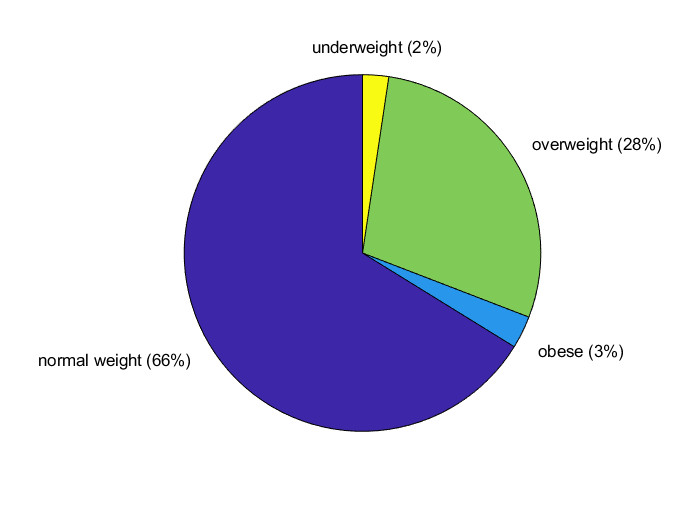

% Pie charts for visualizing the size of each group. This was used to
% determine if the sample sizes of the different groups were large enough
% to compare them in our study. 
pie(subject_info.BMI_group)

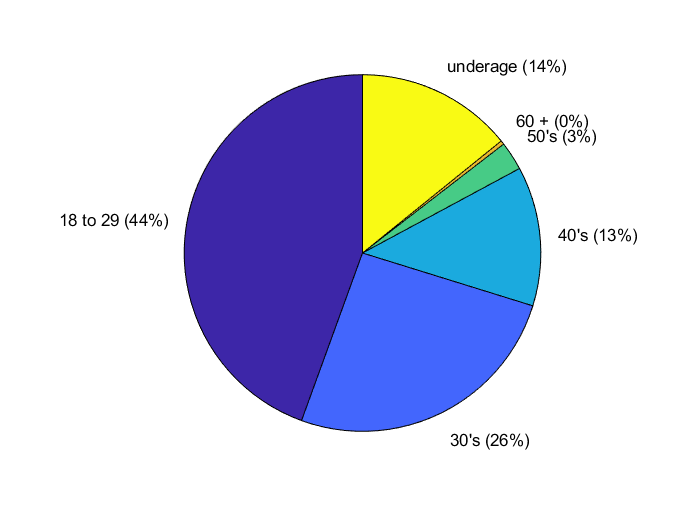

pie(subject_info.age_group)

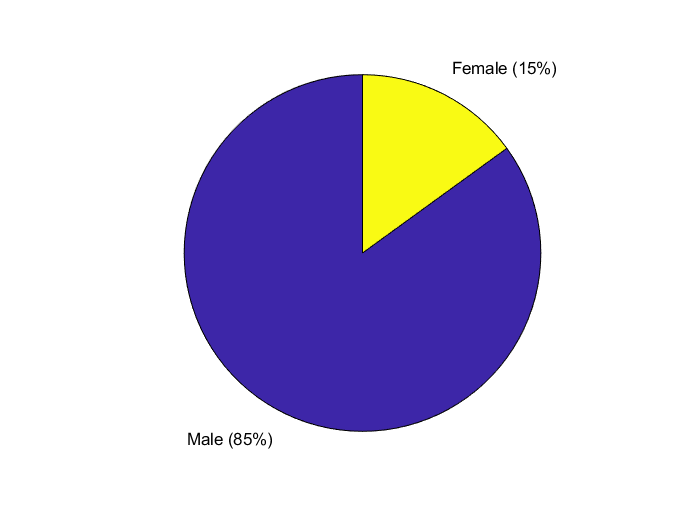

pie(subject_info.Sex)

## Organizing HR & VO2 measurements in Structure by Speed

% Convert data into array type. This is necessary to be able to perform
% arithmetic operations.
data = table2array(data_table);

% The range of speeds that were reached by any of the subjects
% (23.1 km/h was the maximum speed reached by any of the subjects)
speed_overall = (5.1:0.1:23.1)';

% Initialize structure to store heart rate and VO2 of all the subjects for each speed
data_by_speed= struct;

% Add relevant fields to data_by_speed structure
for idx = 1:numel(speed_overall) % for each speed
    % Rows where the speed was equal to speed(idx) 
    row = abs(data(:,2)-speed_overall(idx)) < 1e-12; 
    
    data_by_speed(idx).HR = data(row,3); % HR stores heart rate data
    data_by_speed(idx).VO2 = data(row,4);% VO2 stores oxygen consumption
    data_by_speed(idx).speed = speed_overall(idx);% speed stores the speed for which the data corresponds to
end

## Average HR & VO2 for each speed

% Initialize 2 table to store the average heart rate and oxygen consumption
% for different groups at different speeds. 
average_HR = table; % Stores average heart rate
average_VO2 = table;% Stores average oxygen consumption 

average_HR.speed = speed_overall;
average_VO2.speed = speed_overall;

% Initialize arrays to keep track of the average HR and average VO2
avg_HR = []';
avg_VO2 = []';

% Insert into the arrays the average heart rate and average VO2 for each
% speed
for idx = 1:numel(data_by_speed)
    avg_HR(idx) = mean(data_by_speed(idx).HR);
    avg_VO2(idx) = mean(data_by_speed(idx).VO2);
end

% Add column to average_HR with avg_HR for entire dataset
average_HR.dataset = avg_HR';

% Add column to average_VO2 with avg_VO2 for entire dataset
average_VO2.dataset = avg_VO2';

## Normal Weight Subjects

Organize data from normal weight subjects into structure named "normalw_data_by_speed"

% normal_w creates a table with subject info for "normal weight" subjects
normal_w = subject_info(subject_info.BMI_group == 'normal weight',:);

% Create empty array normalw_data to track data collected from "normal
% weight" subjects 
normalw_data = nan(271140,5);

for idx = 1:numel(normal_w.ID)
    row = data(:,5) == normal_w.ID(idx);
    
    normalw_data = [normalw_data;data(row,:)];
end

% normalw_data_by_speed is an empty structure where the HR and VO2 for the
% "normal weight" subjects will be contained.  
normalw_data_by_speed = struct;

for idx = 1:numel(speed_overall)
    row = abs(normalw_data(:,2)-speed_overall(idx)) < 1e-12;
    
    normalw_data_by_speed(idx).HR = normalw_data(row,3);
    normalw_data_by_speed(idx).VO2 = normalw_data(row,4);
    normalw_data_by_speed(idx).speed = speed_overall(idx); 
end

Calculate average HR and VO2 for normal weight subjects at different speeds and insert these values into the average_HR and average_VO2 tables.

% avg_normal_HR and avg_normal_VO2 are two empty arrays that will contain
% the average HR and the average VO2 for "normal weight" subjects at
% different speeds.
avg_HR = nan(1,181);
avg_VO2 = nan(1,181);

for idx = 1:numel(normalw_data_by_speed)
    avg_HR(idx) = mean(normalw_data_by_speed(idx).HR);
    avg_VO2(idx) = mean(normalw_data_by_speed(idx).VO2);
end

average_HR.Normal_Weight = avg_HR';
average_VO2.Normal_Weight = avg_VO2';

## Overweight Subjects

Organize data from overweight subjects into structure named "overweight_data_by_speed"

% overweight creates a table with the subject info for those that are
% overweight
overweight = subject_info(subject_info.BMI_group == 'overweight',:);

% overweight_data contains the data collected from individuals that are overweight.
% This is an array. 
overweight_data = [];

for idx = 1:numel(overweight.ID)
    row = data(:,5) == overweight.ID(idx);
    
    overweight_data = [overweight_data;data(row,:)];
end

% speed_over is an array that contains the speeds that "overweight" subjects went at.
speed = [6.1:0.1:21.9]'; 

% over_data_by_speed is an empty structure where the HR and VO2 for the
% "overweight" subjects will be contained.  
over_data_by_speed = struct;

for idx = 1:numel(speed)
    row = abs(overweight_data(:,2)-speed(idx)) < 1e-12;
    
    over_data_by_speed(idx).HR = overweight_data(row,3);
    over_data_by_speed(idx).VO2 = overweight_data(row,4);
    over_data_by_speed(idx).speed = speed(idx); 
end

Calculate average HR and VO2 for overweight subjects at different speeds and insert these values into the average_HR and average_VO2 tables.

% avg_over_HR and avg_over_VO2 are two empty arrays that will contain
% the average HR and the average VO2 for "overweight" subjects at
% different speeds.
avg_HR = nan(1,181);
avg_VO2 = nan(1,181);

for idx = 1:numel(over_data_by_speed)
    avg_HR(idx) = mean(over_data_by_speed(idx).HR);
    avg_VO2(idx) = mean(over_data_by_speed(idx).VO2);
end

average_HR.Overweight = avg_HR';
average_VO2.Overweight = avg_VO2';

## Twenties Data

Organize data from 18 to 29 year old subjects into structure named "twenties_data_by_speed"

% twenties creates a table with the subject info for those between 
% 18 to 29 years old
twenties = subject_info(subject_info.age_group == '18 to 29',:);

%twenties_data contains the data collected from individuals between 
% 18 to 29 years old.This is an array. 
twenties_data = [];

for idx = 1:numel(twenties.ID)
    row = data(:,5) == twenties.ID(idx);
    
    twenties_data = [twenties_data;data(row,:)];
end

% twenties_data_by_speed is an empty structure where the HR and VO2 for
% "18 to 29" subjects will be contained.  
twenties_data_by_speed = struct;

for idx = 1:numel(speed_overall)% speed_normal is all the speeds
    row = abs(twenties_data(:,2)-speed_overall(idx)) < 1e-12;
    
    twenties_data_by_speed(idx).HR = twenties_data(row,3);
    twenties_data_by_speed(idx).VO2 = twenties_data(row,4);
    twenties_data_by_speed(idx).speed = speed_overall(idx); 
end

Calculate average HR and VO2 for 18 to 29 year old subjects at different speeds and insert these values into the average_HR and average_VO2 tables.

% avg_over_HR and avg_over_VO2 are two empty arrays that will contain
% the average HR and the average VO2 for 18-29 year old subjects at
% different speeds.
avg_HR = nan(1,181);
avg_VO2 = nan(1,181);

for idx = 1:numel(twenties_data_by_speed)
    avg_HR(idx) = mean(twenties_data_by_speed(idx).HR);
    avg_VO2(idx) = mean(twenties_data_by_speed(idx).VO2);
end

average_HR.Twenties = avg_HR';
average_VO2.Twenties = avg_VO2';

## Thirties Data

Organize data from 30 to 39 year old subjects into structure named "thirties_data_by_speed"

% thirties creates a table with the subject info for those between
% 30 to 39 years old
thirties = subject_info(subject_info.age_group == "30's",:);

%twenties_data contains the data collected from individuals between 
% 18 to 29 years old.This is an array. 
thirties_data = [];

for idx = 1:numel(thirties.ID)
    row = data(:,5) == thirties.ID(idx);
    
    thirties_data = [thirties_data;data(row,:)];
end

%thirties_data_by_speed is an empty structure where the HR and VO2 for
%"30's" subjects will be contained.  
thirties_data_by_speed = struct;

speed = [5.1:0.1:22.7]';

for idx = 1:numel(speed)% speed_normal is all the speeds
    row = abs(thirties_data(:,2)-speed(idx)) < 1e-12;
    
    thirties_data_by_speed(idx).HR = thirties_data(row,3);
    thirties_data_by_speed(idx).VO2 = thirties_data(row,4);
    thirties_data_by_speed(idx).speed = speed(idx); 
end

Calculate average HR and VO2 for 30 to 39 year old subjects at different speeds and insert these values into the average_HR and average_VO2 tables.

% avg_30s_HR and avg_30s_VO2 are two empty arrays that will contain
% the average HR and the average VO2 for "30s" subjects at
% different speeds.
avg_HR = nan(1,181);
avg_VO2 = nan(1,181);

for idx = 1:numel(thirties_data_by_speed)
    avg_HR(idx) = mean(thirties_data_by_speed(idx).HR);
    avg_VO2(idx) = mean(thirties_data_by_speed(idx).VO2);
end

average_HR.Thirties = avg_HR';
average_VO2.Thirties = avg_VO2';

## Forties Data

Organize data from 40 to 49 year old subjects into structure named "forties_data_by_speed"

% forties creates a table with the subject info for those between
% 40 to 49 years old
forties = subject_info(subject_info.age_group == "40's",:);

% forties_data contains the data collected from individuals between 
% 40 to 49 years old.This is an array. 
forties_data = [];

for idx = 1:numel(forties.ID)
    row = data(:,5) == forties.ID(idx);
    
    forties_data = [forties_data;data(row,:)];
end

% forties_data_by_speed is an empty structure where the HR and VO2 for
% "40's" subjects will be contained.  
forties_data_by_speed = struct;

speed = [5.1:0.1:20]';

for idx = 1:numel(speed)% speed_normal is all the speeds
    row = abs(forties_data(:,2)-speed(idx)) < 1e-12;
    
    forties_data_by_speed(idx).HR = forties_data(row,3);
    forties_data_by_speed(idx).VO2 = forties_data(row,4);
    forties_data_by_speed(idx).speed = speed(idx); 
end

Calculate average HR and VO2 for 40 to 49 year old subjects at different speeds and insert these values into the average_HR and average_VO2 tables.

% avg_30s_HR and avg_30s_VO2 are two empty arrays that will contain
% the average HR and the average VO2 for "30s" subjects at
% different speeds.
avg_HR = nan(1,181);
avg_VO2 = nan(1,181);

for idx = 1:numel(forties_data_by_speed)
    avg_HR(idx) = mean(forties_data_by_speed(idx).HR);
    avg_VO2(idx) = mean(forties_data_by_speed(idx).VO2);
end

average_HR.Forties = avg_HR';
average_VO2.Forties = avg_VO2';

## Linear Regressions for VO2 Data

Due to the trends shown in the data, only the middle section is linearly correlated. Exclude data points before speed 8 and after speed 20.

% Creates new/empty vectors of data that exclude any measruements taken below 8 km/h and
% above 20 km/hr. Done for speed, BMI groups,and age groups here
new_speed = [];
new_VO2_normal = [];
new_VO2_over = [];
new_twenties = [];
new_thirties = [];
new_forties = [];
for idx = 1:length(speed_overall)
    if (speed_overall(idx) > 8 && speed_overall(idx) < 20)
        new_speed = [new_speed speed_overall(idx)];
        new_VO2_normal = [new_VO2_normal average_VO2.Normal_Weight(idx)];
        new_VO2_over = [new_VO2_over average_VO2.Overweight(idx)];
        new_twenties = [new_twenties average_VO2.Twenties(idx)];
        new_thirties = [new_thirties average_VO2.Thirties(idx)];
        new_forties = [new_forties average_VO2.Forties(idx)];
    end
end

#### Normal Weight 

% linear regression for VO2 vs. speed for normal weight group BMI
B_normal_VO2 = [new_speed' ones(length(new_speed),1)];
coeffs_normal_VO2 = B_normal_VO2\new_VO2_normal';
model_normal_VO2 = coeffs_normal_VO2(1).*new_speed + coeffs_normal_VO2(2);
rsq_normal_VO2 = r_squared(model_normal_VO2,new_VO2_normal)

rsq_normal_VO2 = 0.9887

#### Overweight

% some data points were 'Nan'. In order to perform the linear regression,
% new vectors were made without the 'Nan' data. 
avg_over_VO2_scrbd = [];
speed_over_scrbd = [];

for idx = 1:length(new_VO2_over)
    if ~isnan(new_VO2_over(idx))
        avg_over_VO2_scrbd = [avg_over_VO2_scrbd new_VO2_over(idx)];
        speed_over_scrbd = [speed_over_scrbd new_speed(idx)];
    end
end

avg_over_VO2_scrbd = avg_over_VO2_scrbd';


% linear regression for VO2 vs. speed for overweight group BMI
B_over_VO2 = [speed_over_scrbd' ones(length(speed_over_scrbd),1)];
coeffs_over_VO2 = B_over_VO2\avg_over_VO2_scrbd;
model_over_VO2 = coeffs_over_VO2(1).*speed_over_scrbd + coeffs_over_VO2(2);
rsq_over_VO2 = r_squared(model_over_VO2,avg_over_VO2_scrbd')

rsq_over_VO2 = 0.9764

#### Twenties

% linear regression for VO2 vs. speed for subjects between the ages of 18 -
% 29
B_twenties_VO2 = [new_speed' ones(length(new_speed),1)];
coeffs_twenties_VO2 = B_twenties_VO2\new_twenties';
model_twenties_VO2 = coeffs_twenties_VO2(1).*new_speed + coeffs_twenties_VO2(2);
rsq_twenties_VO2 = r_squared(model_twenties_VO2,new_twenties)

rsq_twenties_VO2 = 0.9922

#### Thirties

% need to make a new vector of data because thirties contains some 'Nan'
thirties_scrbd = [];
speed_scrbd_thirties = [];

for idx = 1:length(new_thirties)
    if ~isnan(new_thirties(idx))
        thirties_scrbd = [thirties_scrbd new_thirties(idx)];
        speed_scrbd_thirties = [speed_scrbd_thirties new_speed(idx)];
    end
end
thirties_scrbd = thirties_scrbd';

% regression for thirties VO2 vs speed
B_thirties_VO2 = [speed_scrbd_thirties' ones(length(speed_scrbd_thirties),1)];
coeffs_thirties_VO2 = B_thirties_VO2\thirties_scrbd;
model_thirties_VO2 = coeffs_thirties_VO2(1).*speed_scrbd_thirties + coeffs_thirties_VO2(2);
rsq_thirties_VO2 = r_squared(model_thirties_VO2,thirties_scrbd')

rsq_thirties_VO2 = 0.9317

#### Forties

% need to make a new vector of data because forties contains some 'Nan'
forties_scrbd = [];
speed_scrbd_forties = [];

for idx = 1:length(new_forties)
    if ~isnan(new_forties(idx))
        forties_scrbd = [forties_scrbd new_forties(idx)];
        speed_scrbd_forties = [speed_scrbd_forties new_speed(idx)];
    end
end
forties_scrbd = forties_scrbd';

% regression for thirties VO2 vs speed
B_forties_VO2 = [speed_scrbd_forties' ones(length(speed_scrbd_forties),1)];
coeffs_forties_VO2 = B_forties_VO2\forties_scrbd;
model_forties_VO2 = coeffs_forties_VO2(1).*speed_scrbd_forties + coeffs_forties_VO2(2);
rsq_forties_VO2 = r_squared(model_forties_VO2,forties_scrbd')

rsq_forties_VO2 = 0.9390

### Maximum Heart Rate vs. Age Linear Regression

% regression for maximum heart rate vs age
B_HR_age = [subject_info.Age ones(length(subject_info.Age),1)];
coeff_age = B_HR_age\subject_info.maximum_HR;
model_age = coeff_age(1).*subject_info.Age + coeff_age(2);
rsq__age = r_squared(model_age,subject_info.maximum_HR)

rsq__age = 0.2984

### BMI vs. Age Linear Regression

% regression for BMI vs age
B_bmi_age = [subject_info.Age ones(length(subject_info.Age),1)];
coeff_bmi_age = B_bmi_age\subject_info.BMI;
model_bmi_age = coeff_bmi_age(1).*subject_info.Age + coeff_bmi_age(2);
rsq_bmi_age = r_squared(model_bmi_age,subject_info.BMI)

rsq_bmi_age = 0.0581

## Plot Data

#### Average HR vs Speed

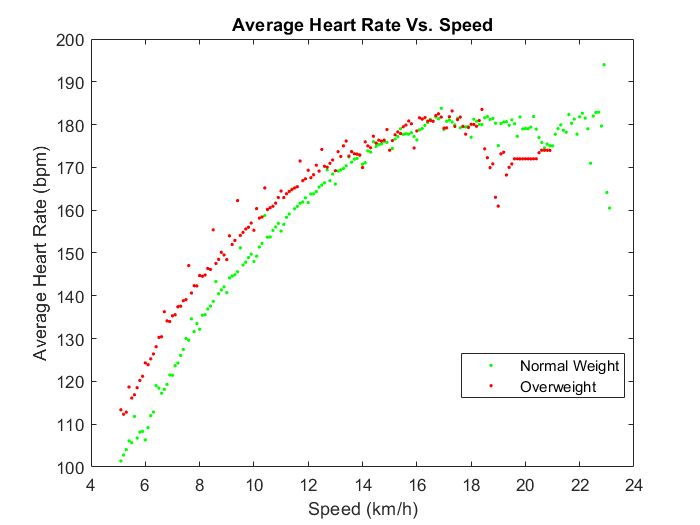

% Plot the Average Heart rate vs Speed for "normal weight" 
% and "overweight"categories
plot(average_HR.speed, average_HR.Normal_Weight, '.','Color','g')
hold on
plot(average_HR.speed,average_HR.Overweight,'.','Color','r')
hold off

title('Average Heart Rate Vs. Speed');
xlabel('Speed (km/h)');
ylabel('Average Heart Rate (bpm)');
legend("Normal Weight","Overweight","Location","best")

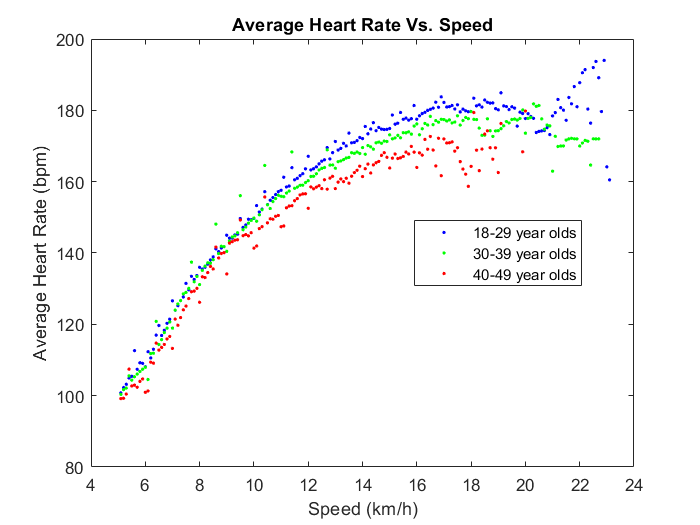



% Plot the Average Heart rate vs Speed by age group
plot(average_HR.speed, average_HR.Twenties, '.','Color','b')
hold on
plot(average_HR.speed,average_HR.Thirties,'.','Color','g')
plot(average_HR.speed,average_HR.Forties,'.','Color','r')
hold off

title('Average Heart Rate Vs. Speed');
xlabel('Speed (km/h)');
ylabel('Average Heart Rate (bpm)');
legend("18-29 year olds","30-39 year olds", "40-49 year olds","Location","best")

#### Average VO2 vs Speed

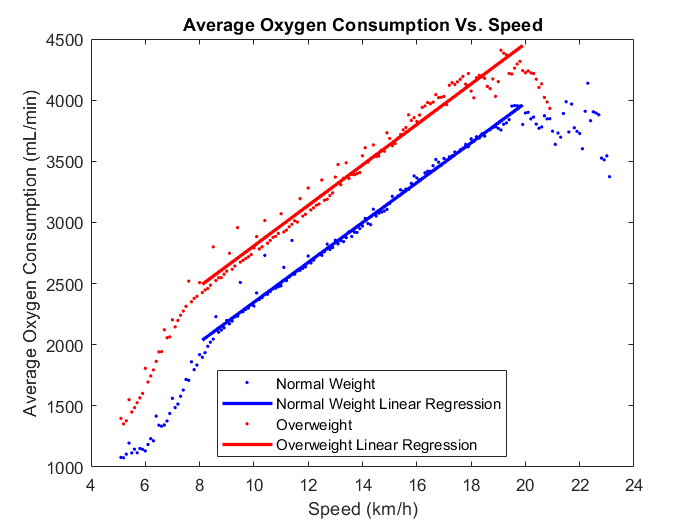

% Plot the Average VO2 vs Speed for normal weight subjects and overweight
% subjects.This plot includes the linear regressions
plot(average_VO2.speed, average_VO2.Normal_Weight, '.','Color','b')
hold on
plot(new_speed,model_normal_VO2,'Color','b','LineWidth',2)
plot(average_VO2.speed, average_VO2.Overweight, '.','Color','r')
plot(speed_over_scrbd,model_over_VO2,'Color','r','LineWidth',2)
hold off

title('Average Oxygen Consumption Vs. Speed');
xlabel('Speed (km/h)');
ylabel('Average Oxygen Consumption (mL/min)');
legend("Normal Weight","Normal Weight Linear Regression","Overweight","Overweight Linear Regression",'Location','best')

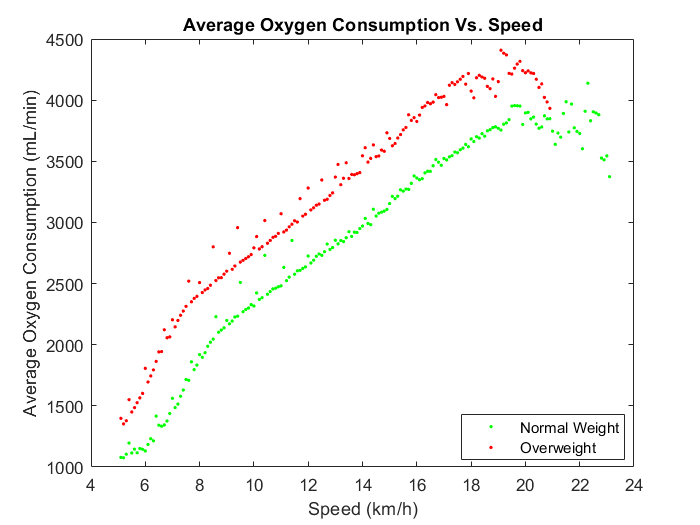


% Plot the Average VO2 vs Speed for normal weight subjects, 
% and overweight subjects. This plot does not include the linear
% regressions
plot(average_VO2.speed, average_VO2.Normal_Weight, '.','Color','g')
hold on
plot(average_VO2.speed, average_VO2.Overweight, '.','Color','r')
hold off

title('Average Oxygen Consumption Vs. Speed');
xlabel('Speed (km/h)');
ylabel('Average Oxygen Consumption (mL/min)');
legend("Normal Weight","Overweight","Location","best")

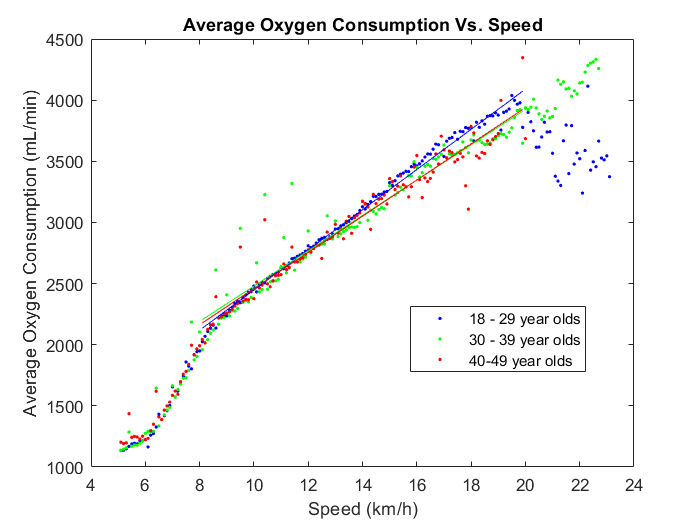


% Plot the Average VO2 vs Speed by age group
plot (average_VO2.speed, average_VO2.Twenties,'.','Color','b')
hold on
plot(average_VO2.speed, average_VO2.Thirties,'.','Color','g')
plot(average_VO2.speed,average_VO2.Forties,'.','Color','r')
plot(new_speed,model_twenties_VO2,'Color','b')
plot(speed_scrbd_thirties,model_thirties_VO2,'Color','g')
plot(speed_scrbd_forties,model_forties_VO2,'Color','r')
hold off

title('Average Oxygen Consumption Vs. Speed');
xlabel('Speed (km/h)');
ylabel('Average Oxygen Consumption (mL/min)');
legend("18 - 29 year olds","30 - 39 year olds","40-49 year olds","Location","best")

#### Maximum HR vs Age

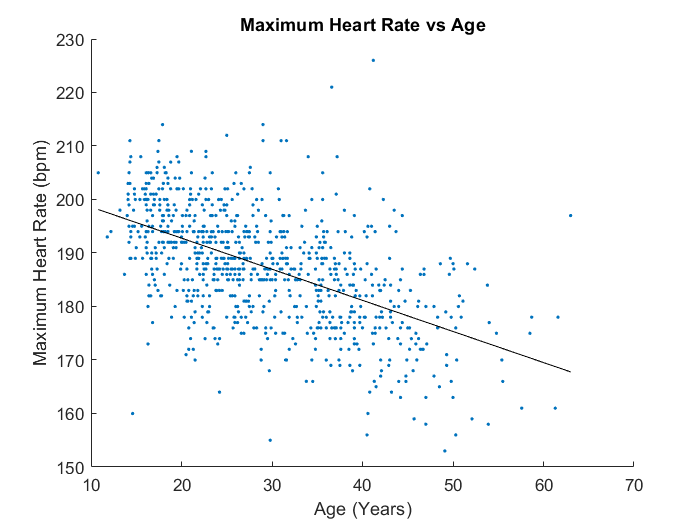

% Plot the maximum HR vs Age for the entire Data Set
scatter(subject_info.Age,subject_info.maximum_HR,'.')
hold on
plot(subject_info.Age,model_age,'Color','k')
hold off

title("Maximum Heart Rate vs Age")
xlabel("Age (Years)")
ylabel("Maximum Heart Rate (bpm)")

#### BMI vs Age

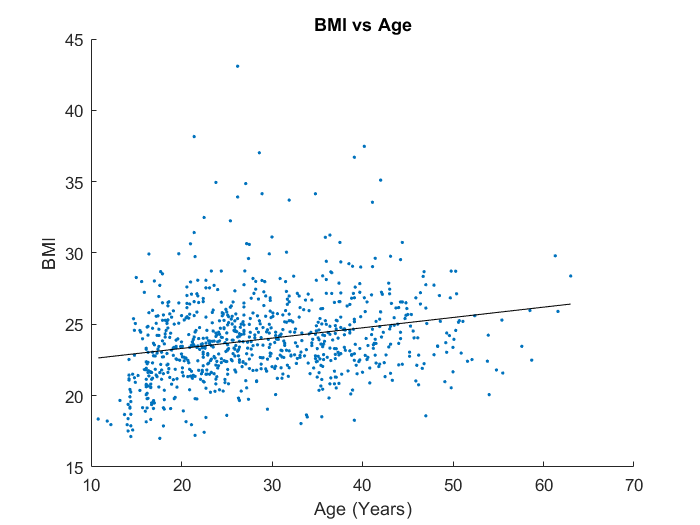

% Plot the BMI vs the age for the entire Data Set
scatter (subject_info.Age,subject_info.BMI,'.')
hold on
plot(subject_info.Age,model_bmi_age,'Color','k')
hold off

title("BMI vs Age")
xlabel("Age (Years)")
ylabel("BMI")

## Heart Rate vs Age

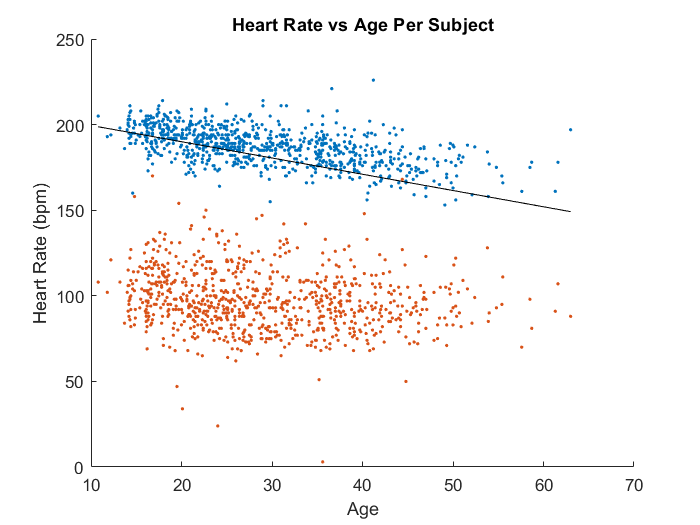

% sub_HR_min and sub_HR_max are two empty arrays that will contain
% each subjects minimum and maxmimum heart rate respectively. 
sub_HR_min = [];
sub_HR_max = [];

% Loop goes through all the subjects and pulls their maximum adn minimum
% heart rate and enters it into the corresponding matrix
for idx = 1:numel(subject_info.ID)
    sub_HR_max(idx) = max(subject(idx).data.HR);
    sub_HR_min(idx) = min(subject(idx).data.HR); 
    sub_HR_max = sub_HR_max';
    sub_HR_min = sub_HR_min';
end

HR_range = [sub_HR_min sub_HR_max];

% Plot the minimum and maximum heart rate for each subject vs their age
scatter(subject_info.Age(:),HR_range(:,2),'.');
hold on
scatter(subject_info.Age(:),HR_range(:,1),'.');
plot(subject_info.Age(:),0.95*(220-subject_info.Age(:)),'Color',[0 0 0]); % This is the line on the plot and it's based on the information from teh literature review. 
hold off

title('Heart Rate vs Age Per Subject')
xlabel('Age')
ylabel('Heart Rate (bpm)')


model = 220 - subject_info.Age;
x = HR_range(:,2);
rsq_maxHr = r_squared(model,x)

rsq_maxHr = 0.0404

clearvars -except average_HR average_VO2 data_table forties normal_w overweight rsq_age rsq_bmi_age rsq_forties_VO2 rsq_maxHr rsq_normal_VO2 rsq_over_VO2 rsq_thirties_VO2 rsq_twenties_VO2 subject_info subject thirties twenties

## Functions used

R-squared

function rsq = r_squared(model,y)
y_res = y - model;
SS_res = sum(y_res.^2);
SS_tot = (length(y)-1) *var(y);
rsq = 1 - SS_res/SS_tot;
SS_reg = SS_tot - SS_res;
end